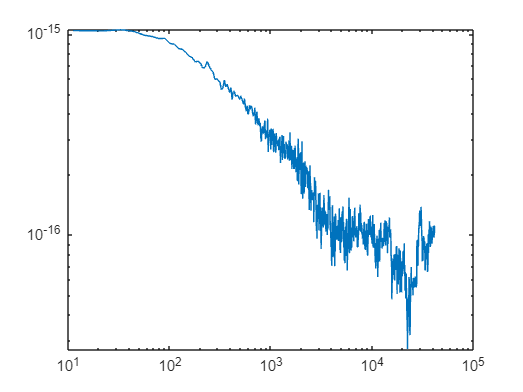

clear all;
load('allan.mat');
time_interval=11.2;
delta=delta/(3e8/780e-9);

for i=1:length(time)/2
    for j=1:floor(length(time)/i)
        y(j)=0;
        for k=1:i
            y(j)=y(j)+delta((j-1)*i+k);
        end
        y(j)=y(j)/i;
    end
    sum=0;
    for j=1:(length(y)-1)
        sum=sum+(y(j+1)-y(j))^2;
    end
    sum=sqrt(sum/(2*(length(y)-1)));
    clear y;
    allan(i)=sum;
    clear sum;
end


timeaxis=[1:length(allan)].*time_interval;
loglog((timeaxis),(allan));

[sig,sig2,osig,msig,tsig,tau]=avar(delta,11.2);

............

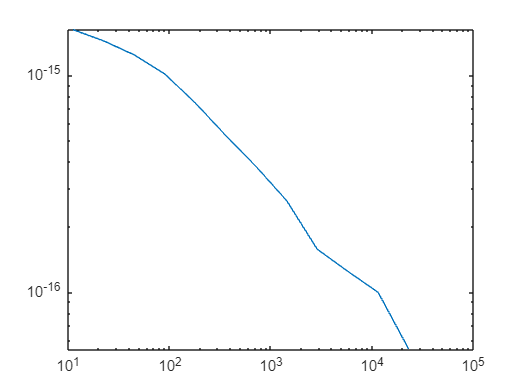

loglog(tau,sig);

allan: allan v2.28

allan: NOTE: There appear to be outliers in the frequency data. See plot.
allan: irregular rate data (no fixed sample rate)
allan: End of timestamp data: 82644.8 sec
       Average rate: 0.0892857 Hz (11.2 sec/measurement)
       Max. gap: 11.2 sec at position 2925
allan: calculating Allan deviation...


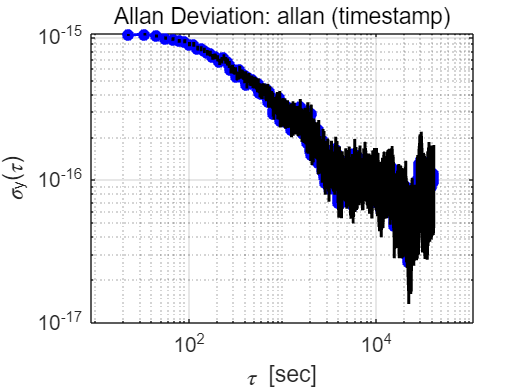

allan: Minimum ADEV value: 2.69696e-17 at tau = 22310.4 seconds




clear allan;
data.freq=delta;
data.time=time;
allan(data,timeaxis,'allan',1);